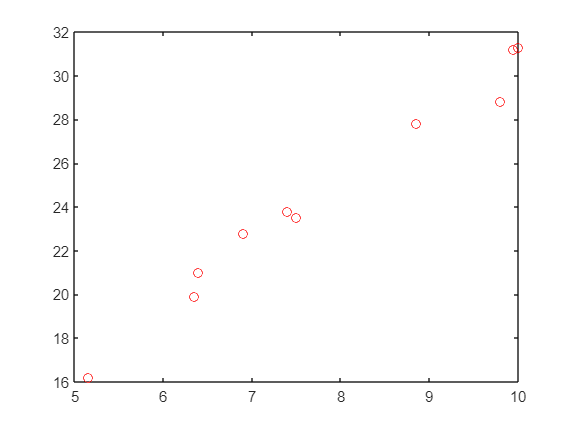

%%Importar datos de excel a matlab
A=xlsread('Practica2.xlsx');
B=xlsread('practica2_2.xlsx');

%%Definir quien es x y quien es y en la grafica
Diametro=A(:,1); 
Perimetro=A(:,2);

%%Graficar nuestros datos para hacer una inspección 
plot(Diametro,Perimetro,'or')

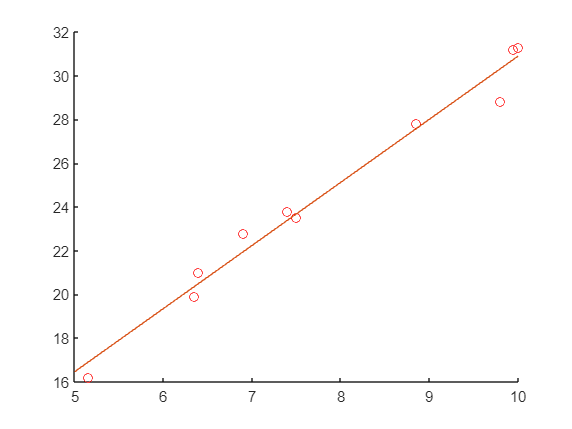


%%C=polyfit(x,y,n) n=1 (ajuste lineal) n=2 (ajuste cuadrático)
C=polyfit(Diametro,Perimetro,1);

%%Graficar los datos con el ajuste
xx=linspace(5,10);
yy=polyval(C,xx);
figure
hold on
plot(Diametro,Perimetro,'or')
plot(xx,yy)
hold off


%%Minimos cuadrados
n = 10; 
x = Diametro;
y = Perimetro;
x2 = B(:,3);
y2 = B(:,4);
xy = B(:,5);

%%Calculo de valores m, b, r, B^2, e(m) y e(b)
m = (n*sum(xy)-sum(x)*sum(y))/(10*sum(x2)-(sum(x))^2)

m = 2.8873

b = (sum(x2)*sum(y)-sum(x)*sum(xy))/(n*sum(x2)-(sum(x))^2)

b = 2.0221

r = (n*sum(xy)-sum(x)*sum(y))/(sqrt(n*sum(x2)-(sum(x))^2)*sqrt(n*sum(y2)-(sum(y))^2))

r = 0.9900

B2 = (b + m*x - y).^2

B2 =     0.4788
    0.2086
    0.0506
    0.2015
    0.0314
    0.2489
    0.1694
    0.7314
    0.1636
    2.3045


sumB2 = sum(B2)

sumB2 = 4.5886

eM = sqrt((n/(n*sum(x2)-(sum(x))^2))*(sum(B2)/(n-2)))

eM = 0.1466

eB = sqrt((sum(x2)/(n*sum(x2)-(sum(x))^2))*(sum(B2)/(n-2)))

eB = 1.1725